Sam Kramer 

Dr. Alfred Wicks

ME 5714: Digital Signal Processing

## Assignment 6a -- DFS of data

%{
    This will be a script that will solve the problems in Assignment 6a. 

    Sam Kramer
    Feb 15th, 2023
%}

% --Script setup
    clear; clc; close all; format compact;

    As a follow-up to assignment 6, a signal (sig1) is shown. It contains random content and a harmonic component at 35.5 Hz. Since we can only calculate integer multiples of w0 from the Fourier series, estimate the amplitude of the component using 35Hz and 36Hz. You might want to try 34Hz and 37Hz as well. What do you get if you try to extract 35.5 Hz directly. 

    Explain the results.

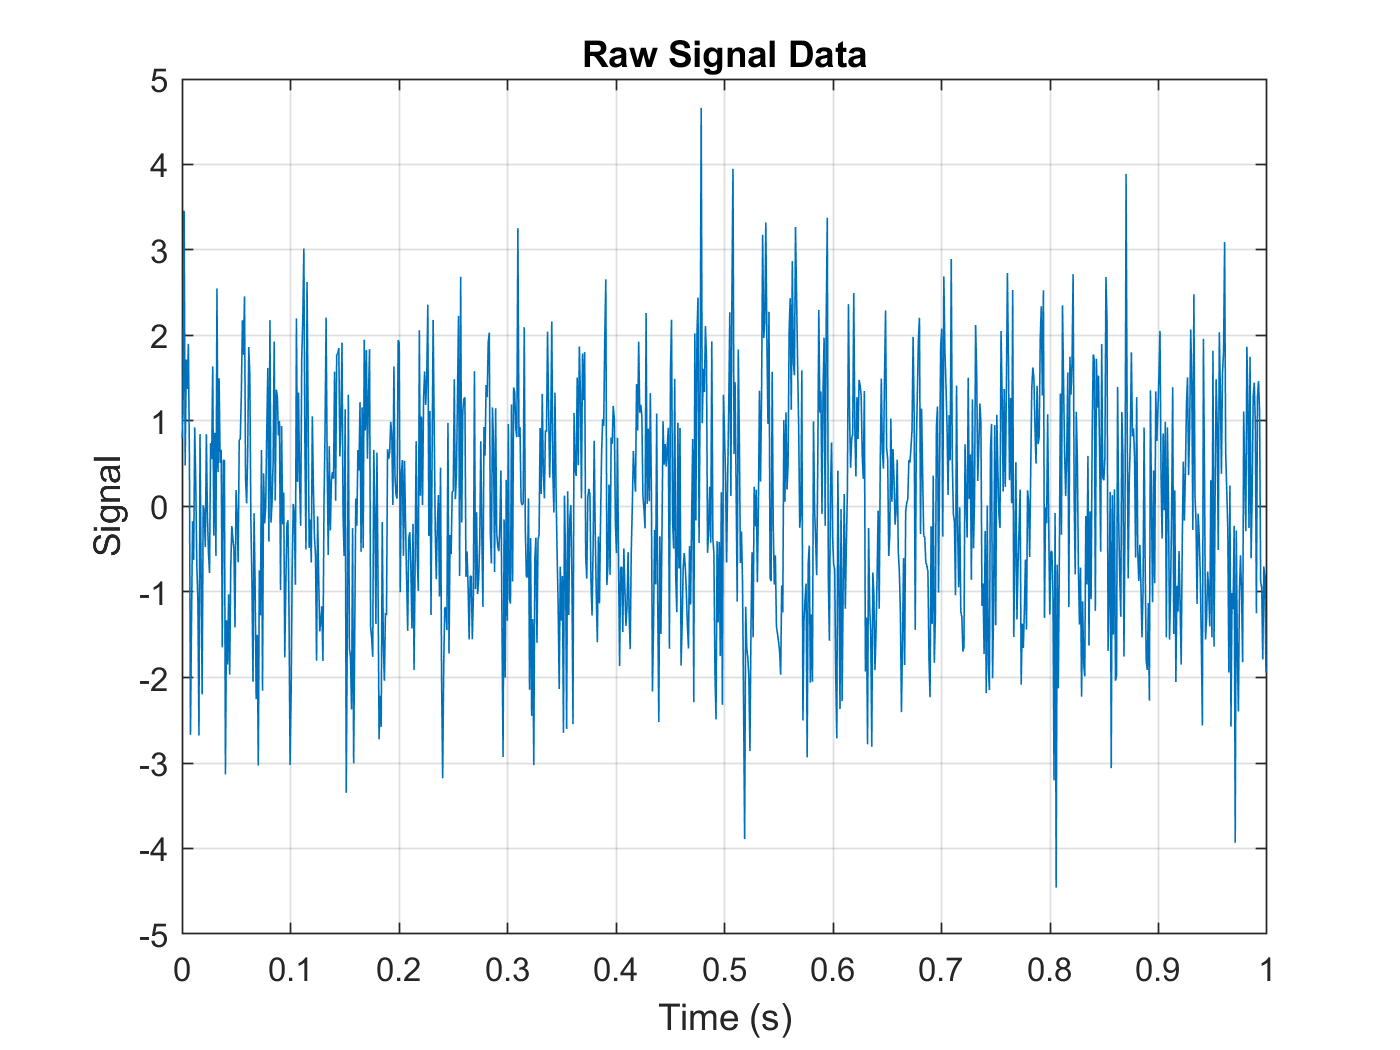

% --Parameters
    fs = 1024;          % Sample Frequency
    magnitude = [];     % magnitude solution Vector
    phase = [];         % Phase solution vector
    magnitude2 = [];    % Ca solution Vector
    
%%%%%%%%%%%%%%%%%%%%%%%%%%%% Initial Data Plotting %%%%%%%%%%%%%%%%%%%%%%%%%
    
% --Load in Data
    a6data = load('6adata.mat');
    
    % --Reformat data
        signal = a6data.sig1;   % Define the signal
        T = a6data.t;           % Define the period
        N = length(signal);
        w0 = 2*pi / 1;                 % Frequency in 
    
% --Plot data
    plot(T,signal);
        title('Raw Signal Data')
        xlabel('Time (s)')
        ylabel('Signal')
        hold on;
        grid on;

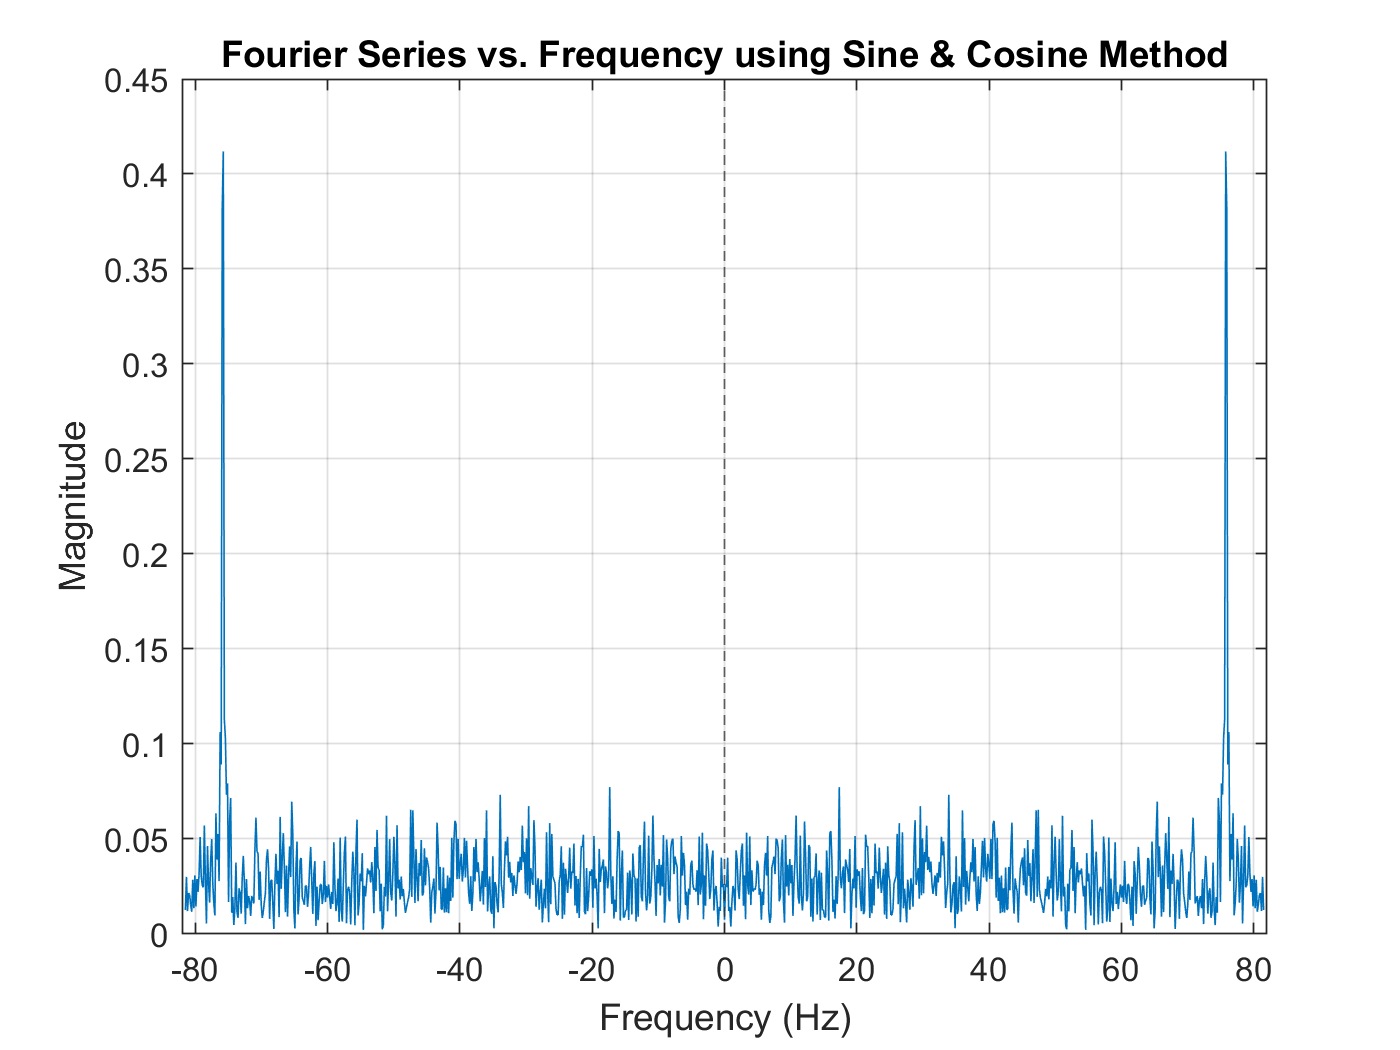

      
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Fourier Series %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
% --Calculate Fourier Series
    for n = 0:N
    
        
        % --Loop Setup
            An = [];
            Bn = [];
            Ca = [];
        
        % --Inner summation term
            for i = 1:N
            
                % --Calculate An and Bn
                a = (signal(i)) * cos(n*w0*T(i));
                b = (signal(i)) * sin(n*w0*T(i));
                c = (signal(i)) * exp(-j * n * w0 * T(i));
                
                % --Sum together An
                An = [An, a];
                Bn = [Bn, b];
                Ca = [Ca, c];
            
            end
            
        % --Normalize values
            An = sum(An)/N;
            Bn = sum(Bn)/N;
            Ca = sum(Ca)/N;
        
        % --Calculate magnitude
            Ca = abs(Ca);
            Cn = sqrt(An^2 + Bn^2);
            phi = atan(Bn / An);
            
        % --Save Values
            magnitude = [magnitude Cn];
            magnitude2 = [magnitude2 Ca];
            phase = [phase phi];
            
            
    end
    
% --reformat Ns
    freq = [-N/2:N/2];
    freq = freq/(2*pi);
    
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Plot %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% --Plot Magnitude vs. Frequency
    figure(3)
    plot(freq,magnitude);
        grid on
        hold on
        xlim([-82 82])
        xline(0,'--')
        xlabel('Frequency (Hz)')
        ylabel('Magnitude')
        title('Fourier Series vs. Frequency using Sine & Cosine Method')

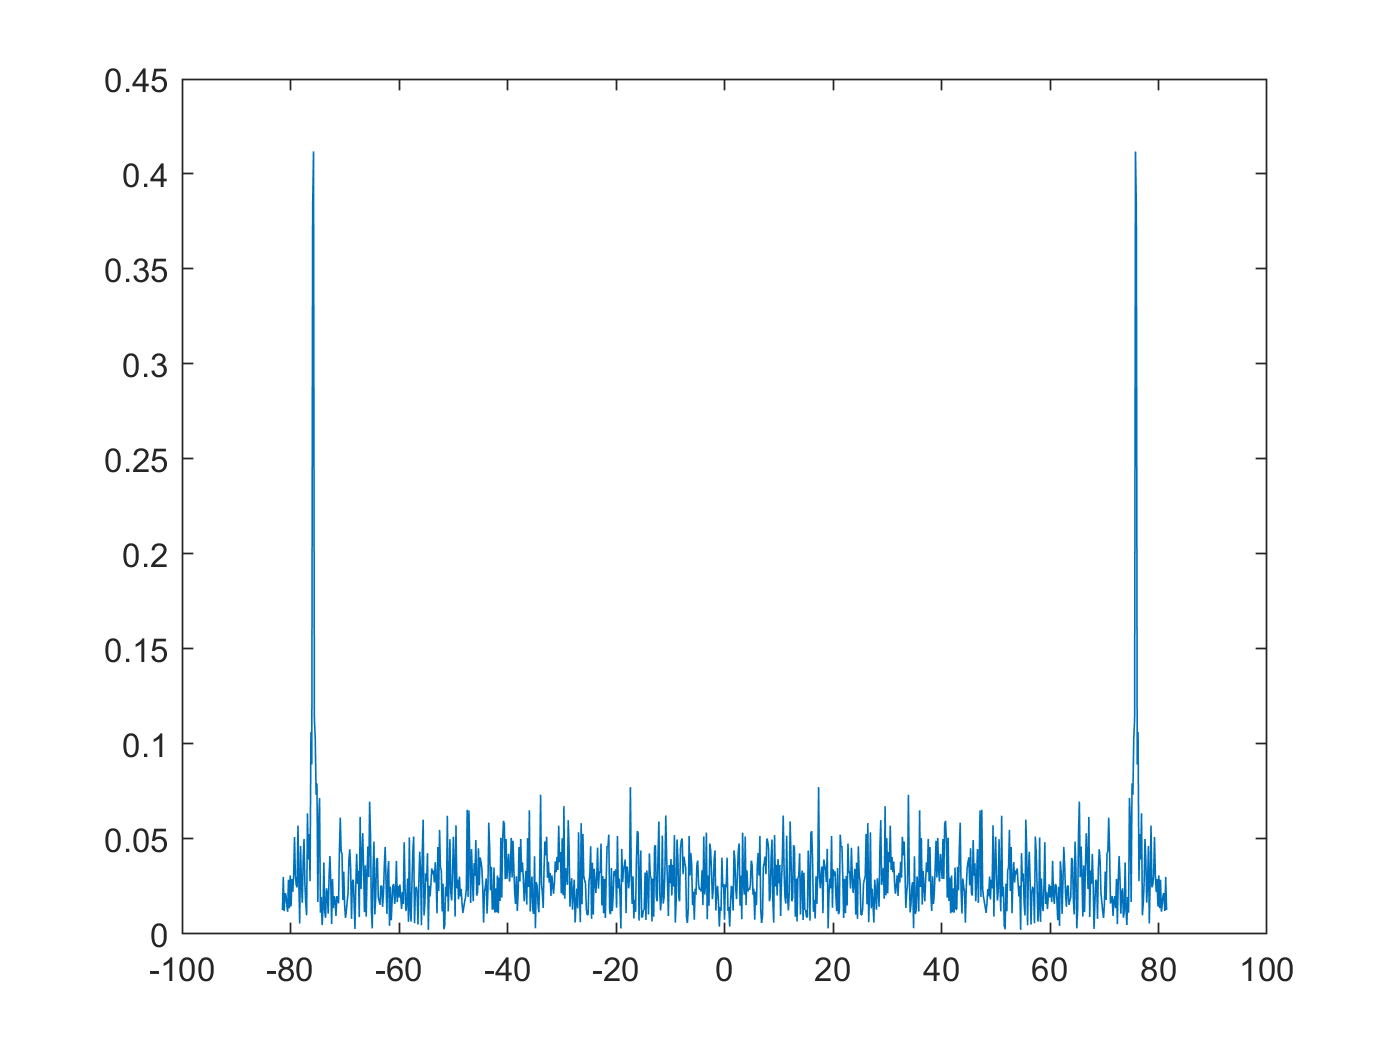

        
    figure(4)
    plot(freq,magnitude2)